# Classification of SARS COVID-19 and Other Lung Infections from Chest X-Ray Scan Images with DenseNet-121

This example shows how to train a deep neural network to classify SARS COVID-19 and other lung infections using chest X-ray (CXR) images. In this example, a transfer learning (TL) based approach is proposed and presented to fine-tune the DenseNet-121 neural network [1] for the CXR image classification task. This example performs classification on the COVID-19 Radiography data set [2-3] using a 2-D DenseNet-121 architecture. 

In comparison to the classification of photographic images, the classification of medical images presents several challenges, such as:

- Unreliable performance due to low inter-class variation between images.

- Potential overfitting due to imbalanced data sets.

Hence, prior to performing TL based classification, it is important to: 

- Select the appropriate deep learning architecture.

- Perform the proper data augmentation techniques.

The 2-D DenseNet-121 [1] is a convolutional network model in which each layer is connected to every other layer in a feed-forward fashion. DenseNets have a number of appealing advantages, including the elimination of the vanishing-gradient problem, improved feature propagation, feature reuse, and a significant reduction in parameter counts. It is also fast, efficient, simple and a popular network in the medical imaging domain [2-3]. This example starts with the ONNX™ DenseNet-121 model (ONNX™ version 1.4, Opset version 9) and applies transfer learning to retrain the network using CXR images.

## Load the Chest X-Ray Data

The COVID-19 Radiography data set [2-3] contains a total of 21165 CXR images, distributed over four classes, which are stored in the following representative folders:

- COVID

- Lung_Opacity

- Normal

- Viral Pneumonia

Create a directory to store the COVID-19 Radiography data set.

dataFolder = fullfile(tempdir,"covid19DataSet");
if ~exist(dataFolder,"dir")
    mkdir(dataFolder)
end

The size of the data set is approximately 800 MB. Download the data set in `.zip` format by clicking on [this link](https://drive.google.com/file/d/1ZMgUQkwNqvMrZ8QaQmSbiDqXOWAewwou/view?usp=sharing). Extract the zip file into the folder specified by `dataFolder`.

Load the COVID-19 Radiography data set images as an image datastore. The `imageDatastore` function automatically labels the images based on folder names and stores the data as an `ImageDatastore` object.

imds = imageDatastore(fullfile(dataFolder,"COVID-19_Radiography_Dataset"),...
    FileExtensions=".png",...
    LabelSource="foldernames",...
    IncludeSubfolders=true);

Count and display the number of CXR image samples for each class.

imds.countEachLabel

ans = 4×2 table
         Label         Count
    _______________    _____

    COVID               3616
    Lung_Opacity        6012
    Normal             10192
    Viral Pneumonia     1345


Set default text and axes tick label interpreters to `"none"`.

initialTextInt = get(groot,"defaulttextInterpreter");
initialAxTickInt = get(groot,"defaultAxesTickLabelInterpreter");
set(groot,defaulttextInterpreter="none")
set(groot,defaultAxesTickLabelInterpreter="none");

Display a random sample of images in the datastore.

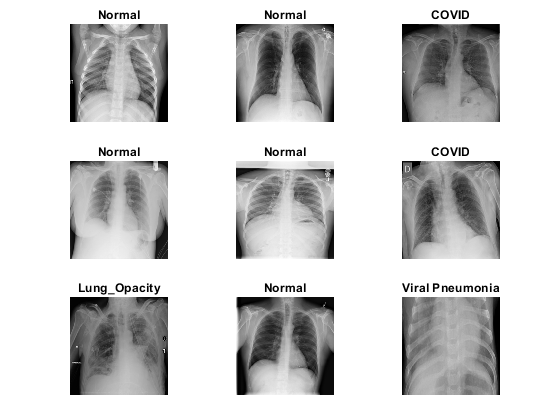

figure
tiledlayout("flow",Padding="compact",TileSpacing="tight")
numTrainImages = numel(imds.Files);
idx = randperm(numTrainImages,9);
for ind = 1:numel(idx)
    nexttile
    imshow(imds.Files{idx(ind)})
    title(string(imds.Labels(idx(ind))))
end

Interactively specify the class label and display random CXR image samples belonging to that class.

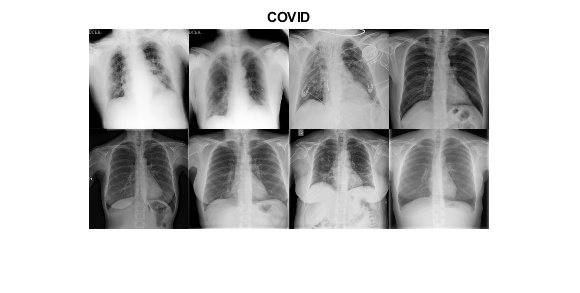

uniqueLabels = unique(imds.Labels);
class = "COVID";
idxClass = find(imds.Labels==class);
numObsToShow = 8;
idx = randi(length(idxClass),1,numObsToShow);

figure
imshow(imtile(imds.Files(idx),GridSize=[2 4],ThumbnailSize=[100 100]))
title(class)

Randomly allocate 80% of the data for training, 10% for testing, and 10% for the validation set.

[imdsTrain,imdsTest,imdsVal] = splitEachLabel(imds,0.8,0.1,0.1,"randomized");
disp("Number of training samples: "+num2str(numel(imdsTrain.Files)))

Number of training samples: 16933


disp("Number of test samples: "+num2str(numel(imdsTest.Files)))

Number of test samples: 2116


disp("Number of validation samples: "+num2str(numel(imdsVal.Files)))

Number of validation samples: 2116


## Import the DenseNet-121 Network

Create a directory to store the ONNX™ DenseNet-121 network.

onnxFolder = fullfile(tempdir,"denseNet121ONNX");
if ~exist(onnxFolder,"dir")
    mkdir(onnxFolder)
end

Import the ONNX™ DenseNet-121 network [1].

denseNet121ONNX_url = "https://github.com/onnx/models/raw/master/vision/classification/densenet-121/model/densenet-9.onnx";
downloadDenseNet121ONNX(denseNet121ONNX_url,onnxFolder);

This can take several minutes to download...
Done.



net = importONNXNetwork(fullfile(onnxFolder,"densenet-9.onnx"),OutputLayerType="classification");

Create a `layerGraph` object.

lgraph = layerGraph(net);

## Modify the DenseNet-121 Network

Specify the size of the image input layer of the imported network to match the size of the images in the image datastores, 128-by-128-by-1.

Replace the existing image input layer with the new image input layer.

newInputLayer = imageInputLayer([128 128 1],Name="newInputLayer");
lgraph = replaceLayer(lgraph,lgraph.Layers(1).Name,newInputLayer);

Update the first 2-D convolution layer to be compatible with the size of new image input layer.

Replace the first 2-D convolution layer with the new 2-D convolution layer.

newConvLayer = convolution2dLayer([7 7],64,Stride=2,Padding=[3 3 3 3],Name="newConv1");
lgraph = replaceLayer(lgraph,lgraph.Layers(2).Name,newConvLayer);

The DenseNet-121 network is trained to recognize 1000 different classes. To adapt the network for chest X-ray classification, adjust the final convolution and classification layers.

First, find the learnable layer and the classification layer.

[learnableLayer,classLayer] = findLayersToReplace(lgraph);

Replace the final convolutional layer, `learnableLayer`, with a new convolutional layer with the number of filters equal to the number of classes.

numClasses = numel(categories(imds.Labels));
newLearnableLayer = convolution2dLayer(1,numClasses,Name="newConvLast");
lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

Replace the existing classification layer with a new classification layer to support four output classes (i.e., COVID, Viral Pneumonia, Lung_Opacity, and Normal).

newClassLayer = classificationLayer(Name="newclassOutput");
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

Analyze the network before training. For more information see [`deepNetworkDesigner`](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html).

deepNetworkDesigner(lgraph)

## Data Augmentation 

Create an image data augmenter that augments the images before training. To avoid overfitting, several standard augmentation procedures such as random rotation, reflection, and scaling are applied to the images. 

Specify the image data augmenter object and input image size.

imageAugmenter = imageDataAugmenter(...
    RandRotation=[-45 45],...
    RandYReflection=true,...
    RandXReflection=true,...
    RandScale=[0.9 1.1]);
imageSize = [128 128 1];

Augment the training image datastore and convert the color modality to grayscale.

augimdsTrain = augmentedImageDatastore(imageSize,imdsTrain,DataAugmentation=imageAugmenter,ColorPreprocessing="rgb2gray");

Update the color modality and size of the test and validation data to match the training data.

imdsTest = augmentedImageDatastore(imageSize,imdsTest,ColorPreprocessing="rgb2gray");
imdsVal = augmentedImageDatastore(imageSize,imdsVal,ColorPreprocessing="rgb2gray");

Pre-process all of the training, testing, and validation images to make the lung region brighter than other regions such as bone and skin. This is inspired by the standard procedure adopted widely by radiologists while investigating X-ray plates manually [3].

The function `preProcessImages` applies the pre-processing steps to the images, and it is attached to the example as a supporting file.

augimdsTrain = transform(augimdsTrain,@preProcessImages,IncludeInfo=true);
imdsTest = transform(imdsTest,@preProcessImages,IncludeInfo=true);
imdsVal = transform(imdsVal,@preProcessImages,IncludeInfo=true);

## Train Network

Specify the training options. For transfer learning, keep the features from the early layers of the network (the transferred layer weights). To slow down learning in the transferred layers, set the initial learning rate to a small value. For this example, train the network for 50 epochs with an initial learning rate of 0.001, a batch size of 128, and use Adam optimization as a solver.

miniBatchSize = 128;
valFrequency = floor(numel(augimdsTrain.UnderlyingDatastores{1}.Files) / miniBatchSize);
options = trainingOptions("adam",...
    MiniBatchSize=miniBatchSize,...
    MaxEpochs=50,...
    InitialLearnRate=1e-3,...
    Shuffle="every-epoch",...
    ValidationData=imdsVal,...
    ValidationFrequency=valFrequency,...
    ExecutionEnvironment="cpu",...
    Verbose=true,...
    Plots="training-progress");

By default, the example loads the pretrained DenseNet-121 network using the `downloadTrainedDenseNet121` helper function. This function is attached to the example as a supporting file. The pretrained network enables you to classify the chest X-ray scans without waiting for the training to complete.

To train the network, set the `doTraining` variable in the following code to `true`. If you choose to train the network, use of a CUDA capable NVIDIA™ GPU is highly recommended. Use of a GPU requires Parallel Computing Toolbox™. For more information about supported GPU devices, see [GPU Support by Release](https://www.mathworks.com/help/parallel-computing/gpu-support-by-release.html) (Parallel Computing Toolbox).

doTraining = false;
if doTraining
    modelDateTime = string(datetime("now",Format="yyyy-MM-dd-HH-mm-ss")); %#ok<UNRCH> 
    trainedNet = trainNetwork(augimdsTrain,lgraph,options);
    save(strcat("covid19_denseNet121_",modelDateTime,"_learningRate_1e-3_maxEpochs_50_adam",".mat"),"trainedNet");
else
    dataFolder = fullfile(tempdir,"DenseNet121Pretrained");
    trainedDenseNet121_url = "https://ssd.mathworks.com/supportfiles/image/data/trainedDenseNet121.mat";
    downloadTrainedDenseNet121(trainedDenseNet121_url,dataFolder);
    load(fullfile(dataFolder,"trainedDenseNet121.mat"));
end

This can take several minutes to download...
Done.



## **Classify Test Images**

Classify the test images using the trained network.

Calculate and display the classification accuracy.

[predLabels,probs] = classify(trainedNet,imdsTest);
testData = readall(imdsTest);
accuracy = mean(predLabels == testData{:,2})

accuracy = 0.9343

Display four sample test images with their predicted labels and the prediction scores.

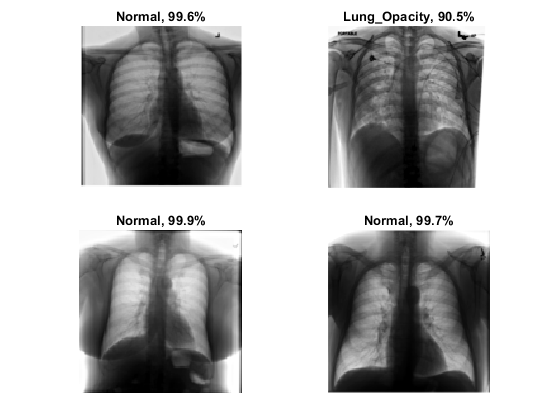

idx = randperm(numel(imdsTest.UnderlyingDatastores{1}.Files),4);
figure
tiledlayout(2,2,Padding="compact",TileSpacing="tight")
for i = 1:4
    imageData = readall(imdsTest);
    I = cell2mat(imageData{idx(i),1});
    nexttile
    imshow(I)
    label = predLabels(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end

Plot the classification confusion matrix

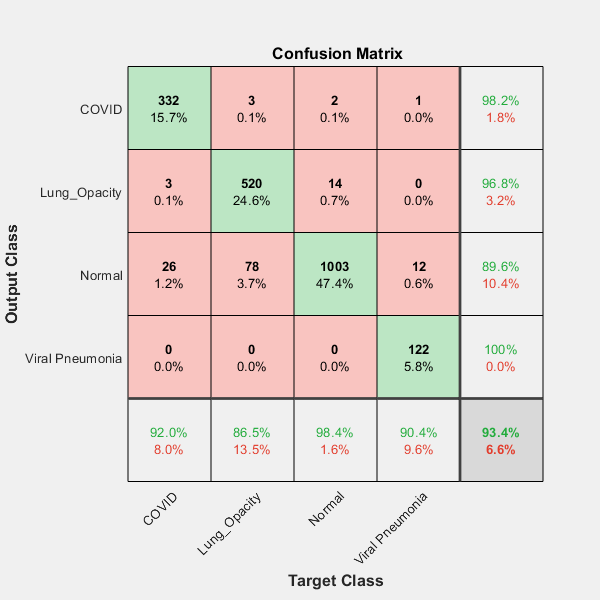

figure
plotconfusion(testData{:,2},predLabels)

On the confusion matrix plot, the rows correspond to the predicted class (Output Class) and the columns correspond to the true class (Target Class). The diagonal cells correspond to observations that are correctly classified. The off-diagonal cells correspond to incorrectly classified observations. The cell in the bottom right of the plot shows the overall accuracy. The confusion matrix shows that the majority of the samples are correctly classified, with an overall accuracy over 90%.

Restore back default text and axes tick label interpreters to their initial values.

set(groot,defaulttextInterpreter=initialTextInt)
set(groot,defaultAxesTickLabelInterpreter=initialAxTickInt)

#### References

- G. Huang, Z. Liu, L. Van Der Maaten, and K. Q. Weinberger, *"Densely Connected Convolutional Networks,"* In Proc. IEEE Conference on Computer Vision and Pattern Recognition (CVPR), 2017, pp. 2261-2269, doi: [10.1109/CVPR.2017.243](https://doi.org/10.1109/CVPR.2017.243).

- M. E. H. Chowdhury, T. Rahman, A. Khandakar, R. Mazhar, M. A. Kadir, Z. B. Mahbub, K. R. Islam, M. S. Khan, A. Iqbal, N. Al-Emadi, M. B. I. Reaz, and M. T. Islam, *"Can AI help in screening Viral and COVID-19 pneumonia?,"* IEEE Access, Vol. 8, 2020, pp. 132665 - 132676, doi: [10.1109/ACCESS.2020.3010287](https://doi.org/10.1109/ACCESS.2020.3010287).

- T. Rahman, A. Khandakar, Y. Qiblawey, A. Tahir, S. Kiranyaz, S. B. A. Kashem, M. T. Islam, S. A. Maadeed, S. M. Zughaier, M. S. Khan, and M. E. Chowdhury, *"Exploring the Effect of Image Enhancement Techniques on COVID-19 Detection using Chest X-ray Images,"* Computers in Biology and Medicine, Vol. 132, 2021, pp. 104319, doi: [10.1016/j.compbiomed.2021.104319](https://doi.org/10.1016/j.compbiomed.2021.104319).

*Copyright 2021 The MathWorks, Inc.*